# CW Laser Tuning Technique

## Microresonator parameters

ring_parameters = dictionary();
ring_parameters("N") = 511; % Number of modes. It must be odd!
ring_parameters("n0") = 2.4; % Refractive index
ring_parameters("n2") = 2.4e-19; % Nonlinear reftactive index [m^2/W]
ring_parameters("FSR") = 100e9; % Free Spectral Range [Hz]
ring_parameters("lambda0") = 1553.4e-9; % CW pump wavelength [m]
ring_parameters("kappa") = 3e8; % Optical linewidth [Hz]
ring_parameters("eta") = 0.5; % Coupling efficiency
ring_parameters("Veff") = 1e-15; % Effective mode volume [m^3]
ring_parameters("D2") = 2.5e6; % Second order dispersion [Hz]
ring_parameters("Pin") = 2; % Pump power [W]

## `Ring 1 - Forward tuning with no effects (Multi-Soliton generation)`

ring1 = Ring(ring_parameters); % Init Ring class

### Simulation parameters

simulation_options_ring1 = dictionary();
simulation_options_ring1("Effects") = "None"; % None or "Thermal" or "Avoided mode crossings"
simulation_options_ring1("Noise") = false; % True or False (White noise)

forward_parameters_ring1 = containers.Map();
forward_parameters_ring1("dseta_start") = -10; % Normalized detuning start
forward_parameters_ring1("dseta_end") = 45; % Normalized detuning end
forward_parameters_ring1("dseta_step") = 0.01; % Tuning step
forward_parameters_ring1("roundtrips_step") = 10; % Roundtrips per tuning step
forward_parameters_ring1("Amu0") = randn(1, ring_parameters("N")) + 1i*randn(1, ring_parameters("N")); % Initial field

### Numerical simulation

tic;
[dseta_forward_ring1, amu_forward_ring1] = ring1.numerical_simulation(forward_parameters_ring1, simulation_options_ring1); % Run forward simulation

FORWARD TUNING: 
Progress: 0%
Progress: 1%
Progress: 2%
Progress: 3%
Progress: 4%
Progress: 5%
Progress: 6%
Progress: 7%
Progress: 8%
Progress: 9%
Progress: 10%
Progress: 11%
Progress: 12%
Progress: 13%
Progress: 14%
Progress: 15%
Progress: 16%
Progress: 17%
Progress: 18%
Progress: 19%
Progress: 20%
Progress: 21%
Progress: 22%
Progress: 23%
Progress: 24%
Progress: 25%
Progress: 26%
Progress: 27%
Progress: 28%
Progress: 29%
Progress: 30%
Progress: 31%
Progress: 32%
Progress: 33%
Progress: 34%
Progress: 35%
Progress: 36%
Progress: 37%
Progress: 38%
Progress: 39%
Progress: 40%
Progress: 41%
Progress: 42%
Progress: 43%
Progress: 44%
Progress: 45%
Progress: 46%
Progress: 47%
Progress: 48%
Progress: 49%
Progress: 50%
Progress: 51%
Progress: 52%
Progress: 53%
Progress: 54%
Progress: 55%
Progress: 56%
Progress: 57%
Progress: 58%
Progress: 59%
Progress: 60%
Progress: 61%
Progress: 62%
Progress: 63%
Progress: 64%
Progress: 65%
Progress: 66%
Progress: 67%
Progress: 68%
Progress: 69%
Progress: 70%

toc;

Elapsed time is 324.413411 seconds.


### Plot results

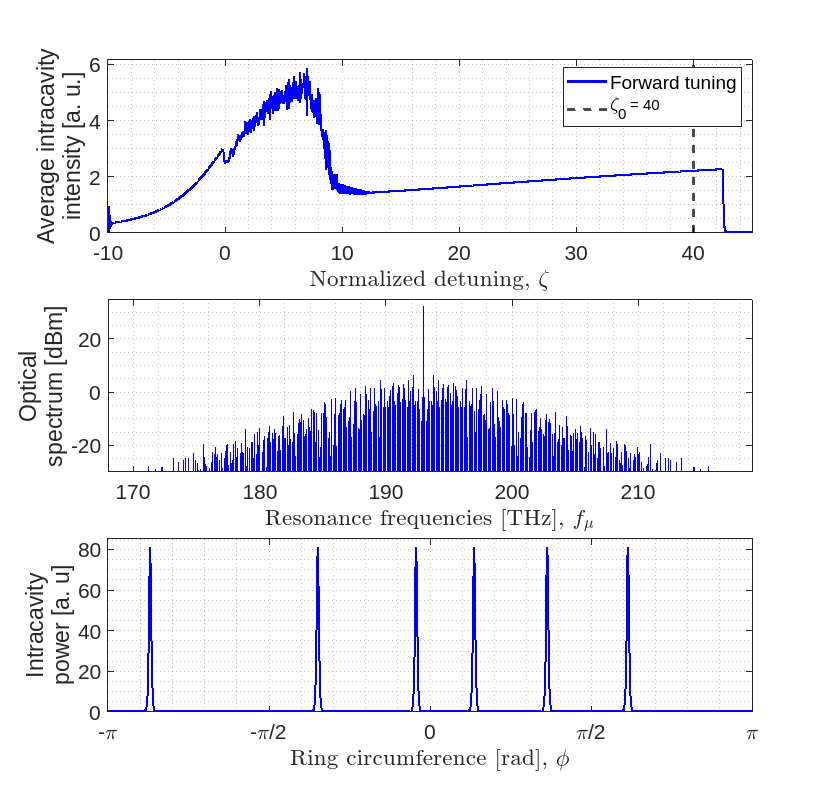

dseta_snap =40;
ring1.plot_results(dseta_forward_ring1, amu_forward_ring1, dseta_snap);

### Save data

data_ring1 = containers.Map();
data_ring1("ring_parameters") = ring_parameters;
data_ring1("simulation_options") = simulation_options_ring1;
data_ring1("forward_parameters") = forward_parameters_ring1;
data_ring1("dseta_forward") = dseta_forward_ring1;
data_ring1("amu_forward") = amu_forward_ring1;

save('data_ring1.mat', "data_ring1");

## `Ring 2 - Forward and backward tuning with thermal effects (Soliton switching)`

ring2 = Ring(ring_parameters); % Init Ring class

### Simulation parameters

simulation_options_ring2 = dictionary();
simulation_options_ring2("Effects") = "Thermal"; % None or "Thermal" or "Avoided mode crossings"
simulation_options_ring2("Noise") = false; % True or False (White noise)

forward_parameters_ring2 = containers.Map();
forward_parameters_ring2("dseta_start") = -10; % Normalized detuning start
forward_parameters_ring2("dseta_end") = 65; % Normalized detuning end
forward_parameters_ring2("dseta_step") = 0.01; % Tuning step
forward_parameters_ring2("roundtrips_step") = 10; % Roundtrips per tuning step
forward_parameters_ring2("Amu0") = randn(1, ring_parameters("N")) + 1i*randn(1, ring_parameters("N")); % Initial field
forward_parameters_ring2("theta0") = 0; % Initial normalized variation of temperature
forward_parameters_ring2("tauT") = 1e-8; % Thermal relaxation time [s]
forward_parameters_ring2("n2T") = 2.4e-18; % Coefficient of thermal nonlinearity [m^2/W]

backward_parameters_ring2 = containers.Map();
backward_parameters_ring2("dseta_start") = 65; % Normalized detuning start
backward_parameters_ring2("dseta_end") = 10; % Normalized detuning end
backward_parameters_ring2("dseta_step") = -0.001; % Tuning step
backward_parameters_ring2("roundtrips_step") = 20; % Roundtrips per tuning step
backward_parameters_ring2("tauT") = 1e-12; % Thermal relaxation time [s]
backward_parameters_ring2("n2T") = 2.4e-18; % Coefficient of thermal nonlinearity [m^2/W]

### Numerical simulation

tic;
[dseta_forward_ring2, amu_forward_ring2, theta_forward_ring2] = ring2.numerical_simulation(forward_parameters_ring2, simulation_options_ring2); % Run forward simulation

FORWARD TUNING: 
Progress: 0%
Progress: 1%
Progress: 2%
Progress: 3%
Progress: 4%
Progress: 5%
Progress: 6%
Progress: 7%
Progress: 8%
Progress: 9%
Progress: 10%
Progress: 11%
Progress: 12%
Progress: 13%
Progress: 14%
Progress: 15%
Progress: 16%
Progress: 17%
Progress: 18%
Progress: 19%
Progress: 20%
Progress: 21%
Progress: 22%
Progress: 23%
Progress: 24%
Progress: 25%
Progress: 26%
Progress: 27%
Progress: 28%
Progress: 29%
Progress: 30%
Progress: 31%
Progress: 32%
Progress: 33%
Progress: 34%
Progress: 35%
Progress: 36%
Progress: 37%
Progress: 38%
Progress: 39%
Progress: 40%
Progress: 41%
Progress: 42%
Progress: 43%
Progress: 44%
Progress: 45%
Progress: 46%
Progress: 47%
Progress: 48%
Progress: 49%
Progress: 50%
Progress: 51%
Progress: 52%
Progress: 53%
Progress: 54%
Progress: 55%
Progress: 56%
Progress: 57%
Progress: 58%
Progress: 59%
Progress: 60%
Progress: 61%
Progress: 62%
Progress: 63%
Progress: 64%
Progress: 65%
Progress: 66%
Progress: 67%
Progress: 68%
Progress: 69%
Progress: 70%

toc;

Elapsed time is 536.369367 seconds.


tic;
[dseta_backward_ring2, amu_backward_ring2, theta_backward_ring2] = ring2.numerical_simulation(backward_parameters_ring2, simulation_options_ring2, dseta_forward_ring2, amu_forward_ring2, theta_forward_ring2); % Run backward simulation

BACKWARD TUNING: 
Progress: 0%
Progress: 1%
Progress: 2%
Progress: 3%
Progress: 4%
Progress: 5%
Progress: 6%
Progress: 7%
Progress: 8%
Progress: 9%
Progress: 10%
Progress: 11%
Progress: 12%
Progress: 13%
Progress: 14%
Progress: 15%
Progress: 16%
Progress: 17%
Progress: 18%
Progress: 19%
Progress: 20%
Progress: 21%
Progress: 22%
Progress: 23%
Progress: 24%
Progress: 25%
Progress: 26%
Progress: 27%
Progress: 28%
Progress: 29%
Progress: 30%
Progress: 31%
Progress: 32%
Progress: 33%
Progress: 34%
Progress: 35%
Progress: 36%
Progress: 37%
Progress: 38%
Progress: 39%
Progress: 40%
Progress: 41%
Progress: 42%
Progress: 43%
Progress: 44%
Progress: 45%
Progress: 46%
Progress: 47%
Progress: 48%
Progress: 49%
Progress: 50%
Progress: 51%
Progress: 52%
Progress: 53%
Progress: 54%
Progress: 55%
Progress: 56%
Progress: 57%
Progress: 58%
Progress: 59%
Progress: 60%
Progress: 61%
Progress: 62%
Progress: 63%
Progress: 64%
Progress: 65%
Progress: 66%
Progress: 67%
Progress: 68%
Progress: 69%
Progress: 70

toc;

Elapsed time is 729.410561 seconds.


### Plot results

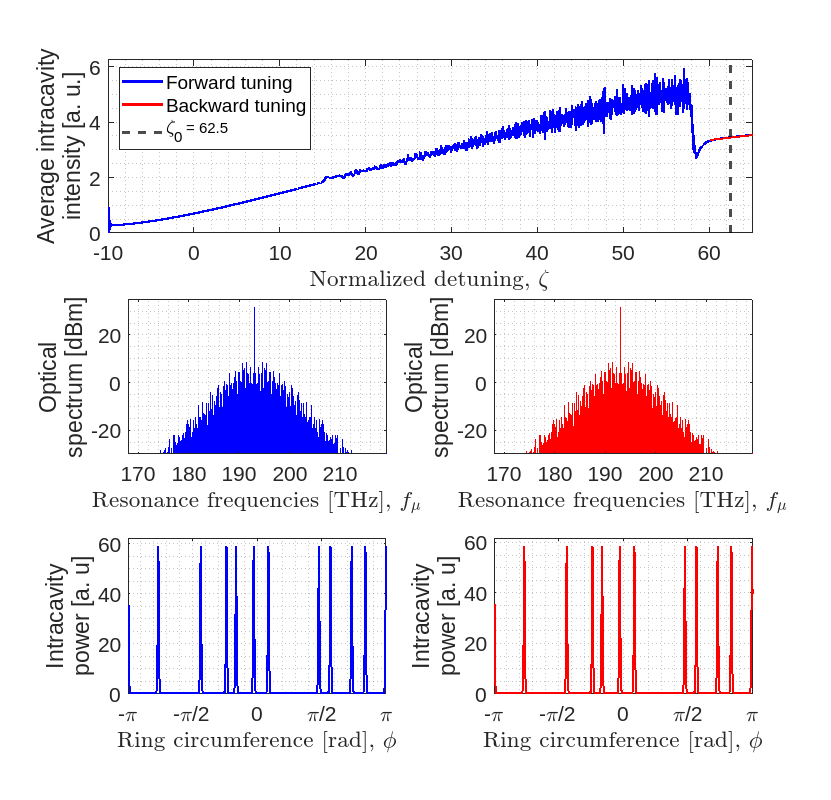

dseta_snap =62.5;
ring2.plot_results(dseta_forward_ring2, amu_forward_ring2, dseta_snap, dseta_backward_ring2, amu_backward_ring2);

### Save data

data_ring2 = containers.Map();
data_ring2("ring_parameters") = ring_parameters;
data_ring2("simulation_options") = simulation_options_ring2;
data_ring2("forward_parameters") = forward_parameters_ring2;
data_ring2("backward_parameters") = backward_parameters_ring2;
data_ring2("dseta_forward") = dseta_forward_ring2;
data_ring2("amu_forward") = amu_forward_ring2;
data_ring2("theta_forward") = theta_forward_ring2;
data_ring2("dseta_backward") = dseta_backward_ring2;
data_ring2("amu_backward") = amu_backward_ring2;
data_ring2("theta_backward") = theta_backward_ring2;

save('data_ring2.mat', "data_ring2");

## `Ring 3 - Forward tuning with avoided mode crossings (Soliton crystal generation)`

ring_parameters("Pin") = 0.5; % Update Pin
ring3 = Ring(ring_parameters); % Init Ring class

### Simulation parameters

simulation_options_ring3 = dictionary();
simulation_options_ring3("Effects") = "Avoided mode crossings"; % None or "Thermal" or "Avoided mode crossings"
simulation_options_ring3("Noise") = false; % True or False (White noise)

forward_parameters_ring3 = containers.Map();
forward_parameters_ring3("dseta_start") = -10; % Normalized detuning start
forward_parameters_ring3("dseta_end") = 12.5; % Normalized detuning end
forward_parameters_ring3("dseta_step") = 0.01; % Tuning step
forward_parameters_ring3("roundtrips_step") = 50; % Roundtrips per tuning step
forward_parameters_ring3("Amu0") = randn(1, ring_parameters("N")) + 1i*randn(1, ring_parameters("N")); % Initial field
forward_parameters_ring3("mode_perturbated") = 15; % Position of the modal crossing

### Numerical simulation

tic;
[dseta_forward_ring3, amu_forward_ring3] = ring3.numerical_simulation(forward_parameters_ring3, simulation_options_ring3); % Run forward simulation

FORWARD TUNING: 
Progress: 0%
Progress: 1%
Progress: 2%
Progress: 3%
Progress: 4%
Progress: 5%
Progress: 6%
Progress: 7%
Progress: 8%
Progress: 9%
Progress: 10%
Progress: 11%
Progress: 12%
Progress: 13%
Progress: 14%
Progress: 15%
Progress: 16%
Progress: 17%
Progress: 18%
Progress: 19%
Progress: 20%
Progress: 21%
Progress: 22%
Progress: 23%
Progress: 24%
Progress: 25%
Progress: 26%
Progress: 27%
Progress: 28%
Progress: 29%
Progress: 30%
Progress: 31%
Progress: 32%
Progress: 33%
Progress: 34%
Progress: 35%
Progress: 36%
Progress: 37%
Progress: 38%
Progress: 39%
Progress: 40%
Progress: 41%
Progress: 42%
Progress: 43%
Progress: 44%
Progress: 45%
Progress: 46%
Progress: 47%
Progress: 48%
Progress: 49%
Progress: 50%
Progress: 51%
Progress: 52%
Progress: 53%
Progress: 54%
Progress: 55%
Progress: 56%
Progress: 57%
Progress: 58%
Progress: 59%
Progress: 60%
Progress: 61%
Progress: 62%
Progress: 63%
Progress: 64%
Progress: 65%
Progress: 66%
Progress: 67%
Progress: 68%
Progress: 69%
Progress: 70%

toc;

Elapsed time is 762.294000 seconds.


### Plot results

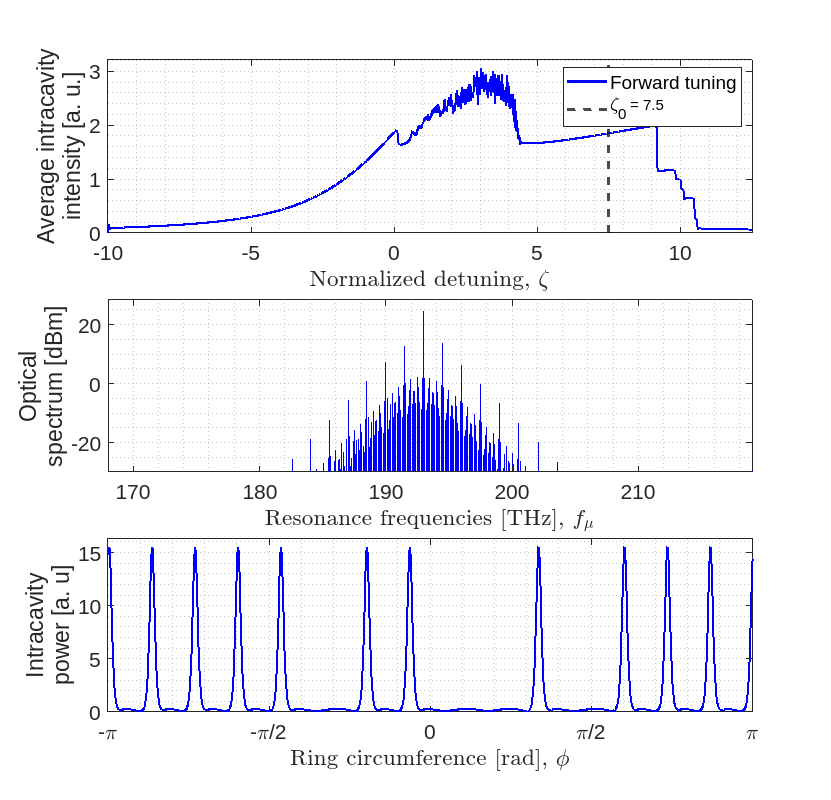

dseta_snap =7.5;
ring3.plot_results(dseta_forward_ring3, amu_forward_ring3, dseta_snap);

### Save data

data_ring3 = containers.Map();
data_ring3("ring_parameters") = ring_parameters;
data_ring3("simulation_options") = simulation_options_ring3;
data_ring3("forward_parameters") = forward_parameters_ring3;
data_ring3("dseta_forward") = dseta_forward_ring3;
data_ring3("amu_forward") = amu_forward_ring3;

save('data_ring3.mat', "data_ring3");

## References

- [https://www.nature.com/articles/nphys3893](https://www.nature.com/articles/nphys3893)

- [https://infoscience.epfl.ch/record/188349](https://infoscience.epfl.ch/record/188349)

- [https://www.nature.com/articles/s41567-019-0635-0](https://www.nature.com/articles/s41567-019-0635-0)

- [https://onlinelibrary.wiley.com/doi/full/10.1002/lpor.201600276](https://onlinelibrary.wiley.com/doi/full/10.1002/lpor.201600276)

- [https://zenodo.org/record/3726531#.X2QMoGhKhPY](https://zenodo.org/record/3726531#.X2QMoGhKhPY)